# COMSA Project data logging demonstration

## Introduction

## Remarks

- **BESS voltage** is measured instead of **Load Power. **This issue is solved.

- The used csv file has 10 columns. There is one additional field is added so called** "Device tag". **This tag is used to personalize the device. For example if a BQ225 sensor is placed on the rooftop, one may set device tag as rooftop BQ225. This is due to I realized that while filtering, to indicate filteirng for which device, using only the device model was not sufficient since there may be more than one device.

Clean up

close all
clearvars
clc

Import **.csv **file where columns

- **Column 1:** Year

- **Column 2:** Month

- **Column 3:** Day

- **Column 4:** Hour

- **Column 5:** Minute

- **Column 6:** Second

- **Column 7:** Operation tag (sensor, inverter, vfd etc..)

- **Column 8:** Device model (BQ225, nivelco etc.)

- `Column 9: Device tag ("One at the greenhouse", "machine laboratory", etc.. ) `

- **Column 9 **`(10)`**:** Tag ( humidity, grid power, load power etc.)

- **Column 10 **`(11)`**:** Value (23.256,  1.235216, "text" etc)..

represents respectively.

csv_file_name = 'default_12_04_2023.csv';
table = readtable(csv_file_name);

filter  and procces the data

start_date =  [2023,4,11,13,35,48];
end_date =  [2023,4,11,23,35,48];
[humidity,t_humidity, humidity_c, t_humidity_c] = filter_data(table,start_date , end_date, "BQ225","humidity");
[tempereature,t_tempereature, tempereature_c, t_tempereature_c] = filter_data(table,start_date , end_date, "BQ225","temperature");

[BESS_voltage,t_BESS_voltage, BESS_voltage_c, t_BESS_voltage_c] = filter_data(table,start_date , end_date, "GROWATT_SPF5000_ES","BESS-voltage");
[load_power,t_load_power, load_power_c, t_load_power_c] = filter_data(table,start_date , end_date, "GROWATT_SPF5000_ES","load-power");
[pv_power,t_pv_power, pv_power_c, t_pv_power_c] = filter_data(table,start_date , end_date, "GROWATT_SPF5000_ES","pv-power");
[calculated_BESS_power,t_calculated_BESS_power, calculated_BESS_power_c, t_calculated_BESS_power_c] = filter_data(table,start_date , end_date, "GROWATT_SPF5000_ES","calculated-BESS-power");
[calculated_BESS_current,t_calculated_BESS_current, calculated_BESS_current_c, t_calculated_BESS_current_c] = filter_data(table,start_date , end_date, "GROWATT_SPF5000_ES","calculated-BESS-current");



Plot data

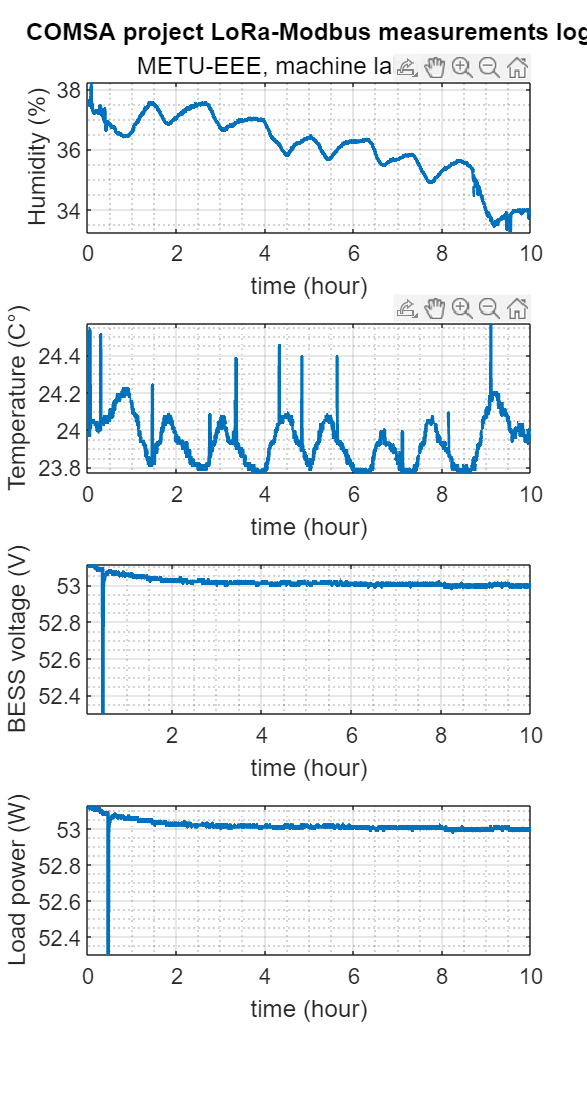

number_of_rows = 4;
number_of_columns = 1;
figure
set(gcf, 'Position', [100, 100, 800, 1500])
subplot(number_of_rows,number_of_columns,1)
plot(t_humidity./3600, humidity,'LineWidth',2)
title('COMSA project LoRa-Modbus measurements log','METU-EEE, machine laboratory')
ylabel('Humidity (%)')
xlabel('time (hour)')
set(gca,'FontSize',12)
grid on
grid minor

subplot(number_of_rows,number_of_columns,2)
plot(t_tempereature./3600,tempereature,'LineWidth',2)
ylabel('Temperature (C°)')
xlabel('time (hour)')
set(gca,'FontSize',12)
grid on
grid minor

subplot(number_of_rows,number_of_columns,3)
plot(t_BESS_voltage./3600,BESS_voltage,'LineWidth',2)
ylabel('BESS voltage (V)')
xlabel('time (hour)')
set(gca,'FontSize',12)
grid on
grid minor

subplot(number_of_rows,number_of_columns,4)
plot(t_load_power./3600,load_power,'LineWidth',2)
ylabel('Load power (W)')
xlabel('time (hour)')
set(gca,'FontSize',12)
grid on
grid minor

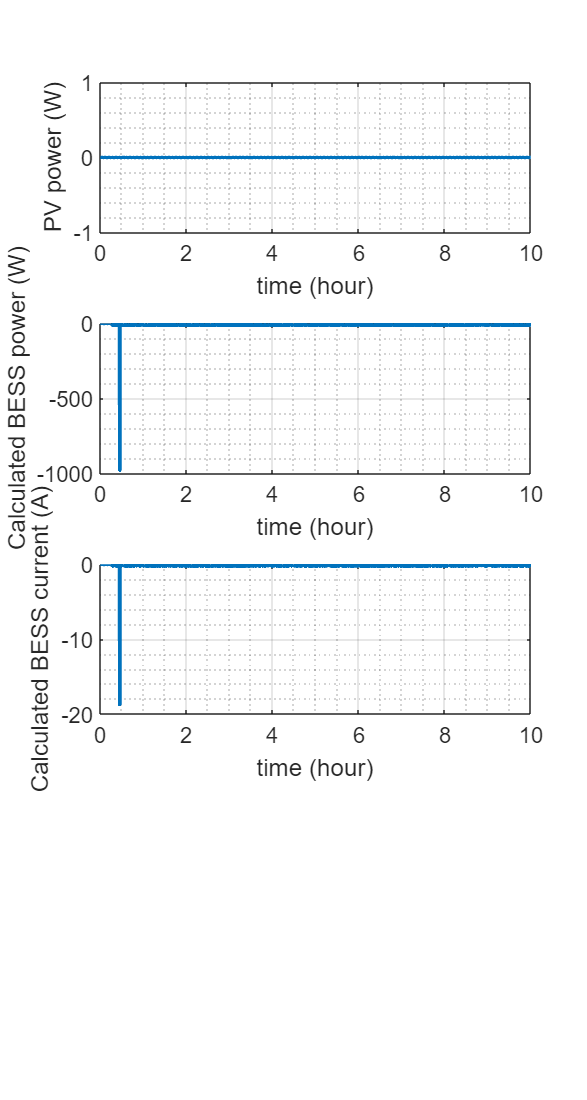


figure
set(gcf, 'Position', [100, 100, 800, 1500])
subplot(number_of_rows,number_of_columns,1)
plot(t_pv_power./3600,pv_power,'LineWidth',2)
ylabel('PV power (W)')
xlabel('time (hour)')
set(gca,'FontSize',12)
grid on
grid minor

subplot(number_of_rows,number_of_columns,2)
plot(t_calculated_BESS_power./3600,calculated_BESS_power,'LineWidth',2)
ylabel('Calculated BESS power (W)')
xlabel('time (hour)')
set(gca,'FontSize',12)
grid on
grid minor

subplot(number_of_rows,number_of_columns,3)
plot(t_calculated_BESS_current./3600,calculated_BESS_current,'LineWidth',2)
ylabel('Calculated BESS current (A)')
xlabel('time (hour)')
set(gca,'FontSize',12)
grid on
grid minor

function [data, data_timestamp_unix, data_corrupted, data_corrupted_timestamp_unix] = filter_data(csv_table, s_date, e_date, device_name, tag)
    data_timestamp_unix = [];
    data = [];
    data_corrupted_timestamp_unix = [];
    data_corrupted = [];
    %csv_table => imported .csv data
    %s_date => start filtering from -> [year,month,day,hour, minute, second]
    %e_date => filter until -> [year, month, day, hour, minute, second]
    %device_name => device name to filter
    % Create a datetime object using the specified values
    d_s = datetime(s_date(1), s_date(2), s_date(3), s_date(4), s_date(5), s_date(6));
    d_e = datetime(e_date(1), e_date(2), e_date(3), e_date(4), e_date(5), e_date(6));
    % Convert the datetime object to Unix time using posixtime function
    u_s = posixtime(d_s);
    u_e = posixtime(d_e);
    
    number_of_rows = height(csv_table);
    for row_no = 1:number_of_rows

        %check if device is the one that data is filtered for
        device = string(csv_table{row_no, 8});
        if device ~= device_name
            continue
        end
        %check if tag is the one that data is filtered for
        tag_candidate = string(csv_table{row_no, 9});
        if tag_candidate ~= tag
            continue
        end
        %check if record in between desired time interval
        d_data = datetime(csv_table{row_no, 1}, csv_table{row_no, 2}, csv_table{row_no, 3}, csv_table{row_no, 4}, csv_table{row_no, 5}, csv_table{row_no, 6});
        u_d = posixtime(d_data);
        if(u_d<u_s || u_d > u_e)
            continue
        end
        data_candidate = csv_table{row_no, 10};
        if isnan(data_candidate)
            data_corrupted = [ data_corrupted  data_candidate];
            data_corrupted_timestamp_unix = [data_corrupted_timestamp_unix (u_d-u_s)];
        else
            data = [data data_candidate];
            data_timestamp_unix = [data_timestamp_unix (u_d-u_s)];
        end
        

    end

end



